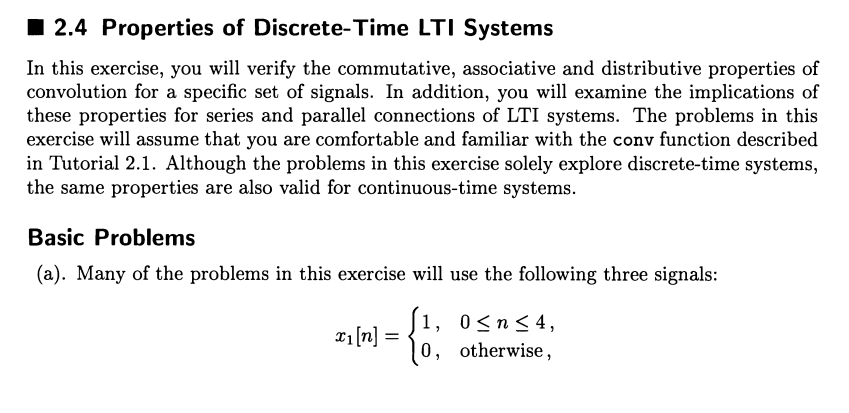

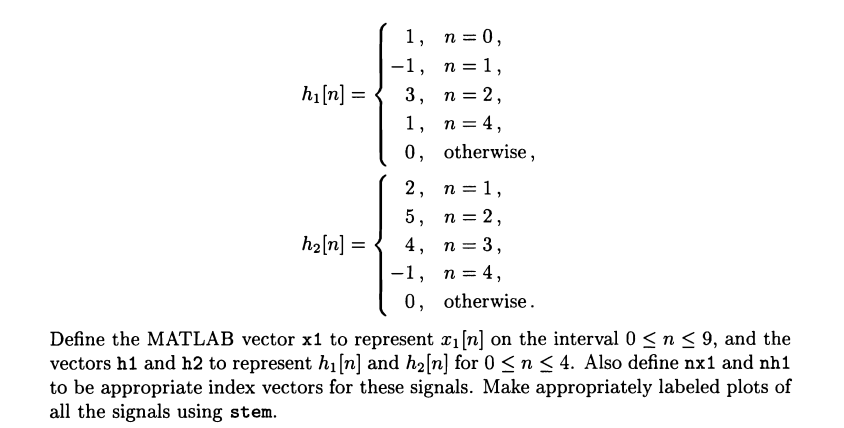

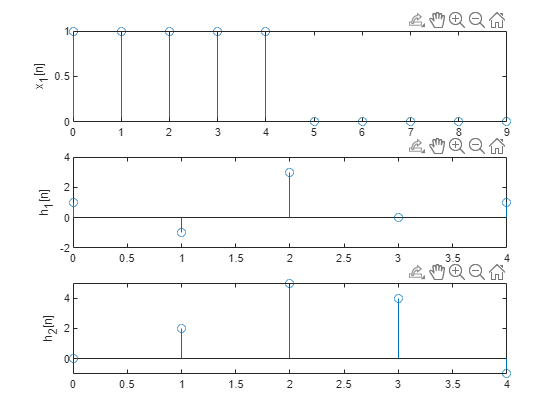

clear; clc; 
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;
f24 = figure;
figure(f24);

subplot(3,1,1);
stem(nx1, x1);
ylabel('x_1[n]');

subplot(3,1,2);
stem(nh1, h1);
ylabel('h_1[n]');

subplot(3,1,3);
stem(nh1, h2);
ylabel('h_2[n]');

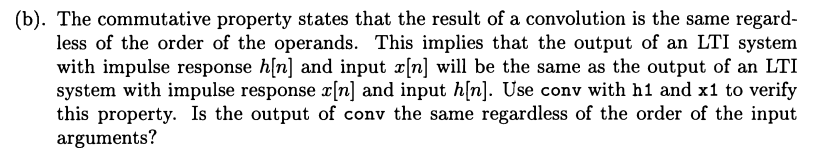

Let y1 = conv(x1, h1), y2 = conv(h1, x1). Check whether they are the same

clear; clc; 
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

y1 = conv(x1, h1);
y2 = conv(h1, x1);
ans = isequal(y1, y2)

ans = logical
   1


y1 and y2 are the same.

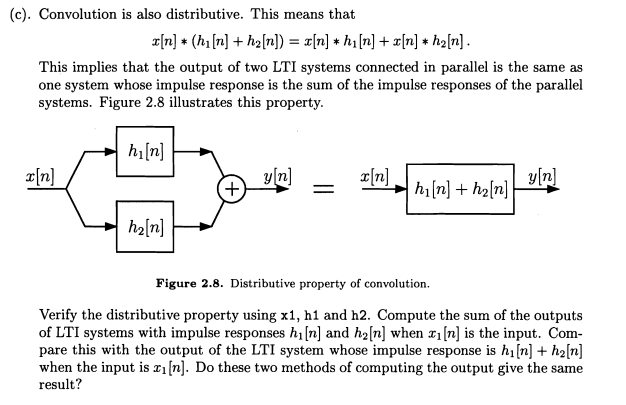

let y1 be the output of the left picture, and y2 be the other.

clear; clc; 
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

y1 = conv(x1, h1) + conv(x1, h2);
y2 = conv(x1, (h1+h2));
ans = isequal(y1, y2)

ans = logical
   1


y1 and y2 are the same.

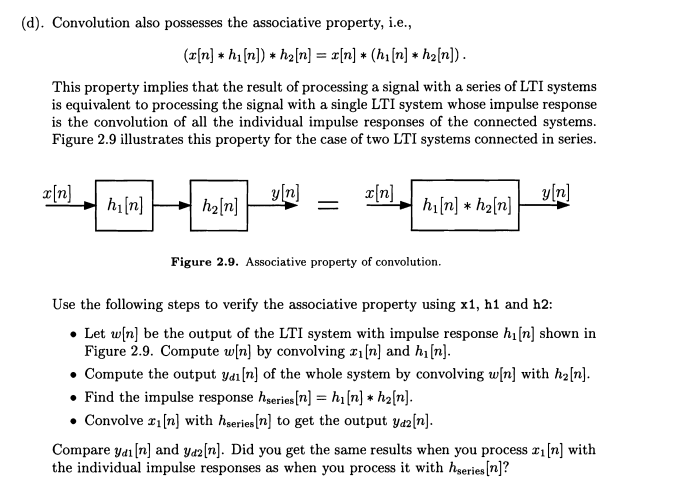

clc; clear;
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

w = conv(x1, h1);
yd1 = conv(w, h2);

h_series = conv(h1, h2);
yd2 = conv(x1, h_series);

ans = isequal(yd1, yd2)

ans = logical
   1


$y_{d1}[n]$ = $y_{d2}[n]$

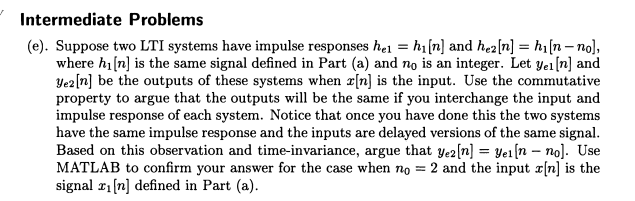

according to commutative property.

conv( $h_1[n]$, x[n] ) = conv(x[n], $h_1[n]$ )

conv( $h_1$ [n - $n_0$ ], x[n]) = conv(x[n], $h_1$ [n - $n_0$ ])

so the output is the same after exchanging input and impulse response.

because the system is time invariant.

and $h_{e2}$[n] = $h_{e1}$[ n - $n_0$ ]

so $y_{e2}$[n] = $y_{e1}$[ n - $n_0$]  

clc; clear;
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

he1 = [h1 0 0];
he2 = [0 0 h1];

ye1 = conv(x1, he1)

ye1 =      1     0     3     3     4     3     4     1     1     0     0     0     0     0     0     0


ye2 = conv(x1, he2)

ye2 =      0     0     1     0     3     3     4     3     4     1     1     0     0     0     0     0


ans = isequal(ye1(1:end-2), ye2(3:end))

ans = logical
   1


the answer is $y_{e2}$[n] = $y_{e1}$[ n - $n_0$]  

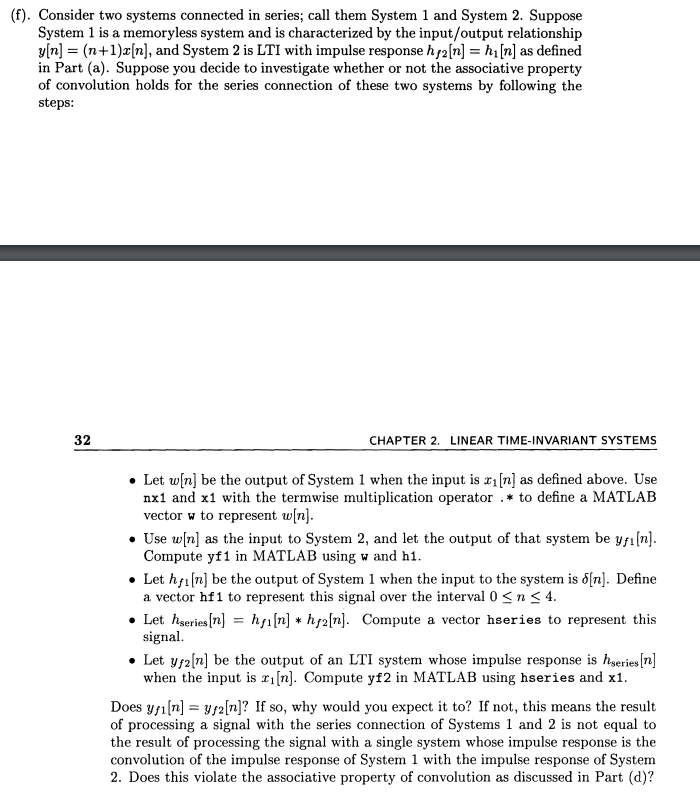

clc; clear;
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;
hf2 = h1;

w = (nx1+1).*x1;
yf1 = conv(w, hf2)

yf1 =      1     1     4     7    11     9    18     4     5     0     0     0     0     0



impu = [1 0 0 0 0];
hf1 = (nh1+1).*impu;

hseries = conv(hf1, hf2);
yf2 = conv(x1, hseries)

yf2 =      1     0     3     3     4     3     4     1     1     0     0     0     0     0     0     0     0     0



ans = isequal(yf1, yf2(1:14))

ans = logical
   0


yf1[n] != yf2[n]. It dosen't violate the associative property. Beacuse system 1 is not time invariant which is simple to find. So w != conv(x1, hf1).

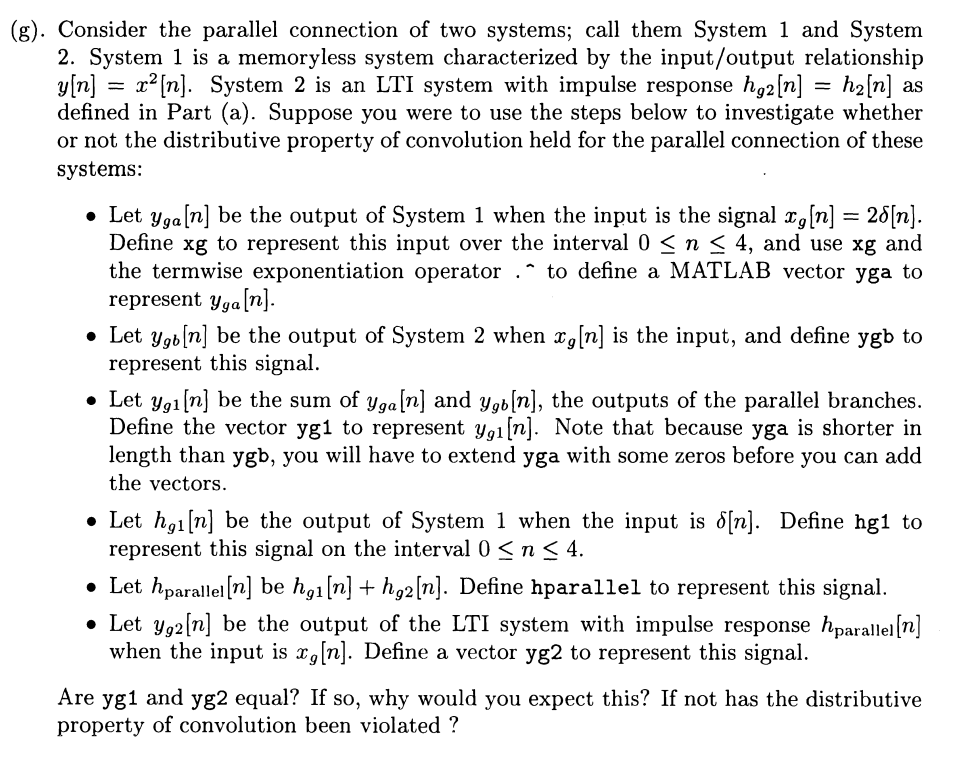

clc; clear;
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;
hf2 = h1;

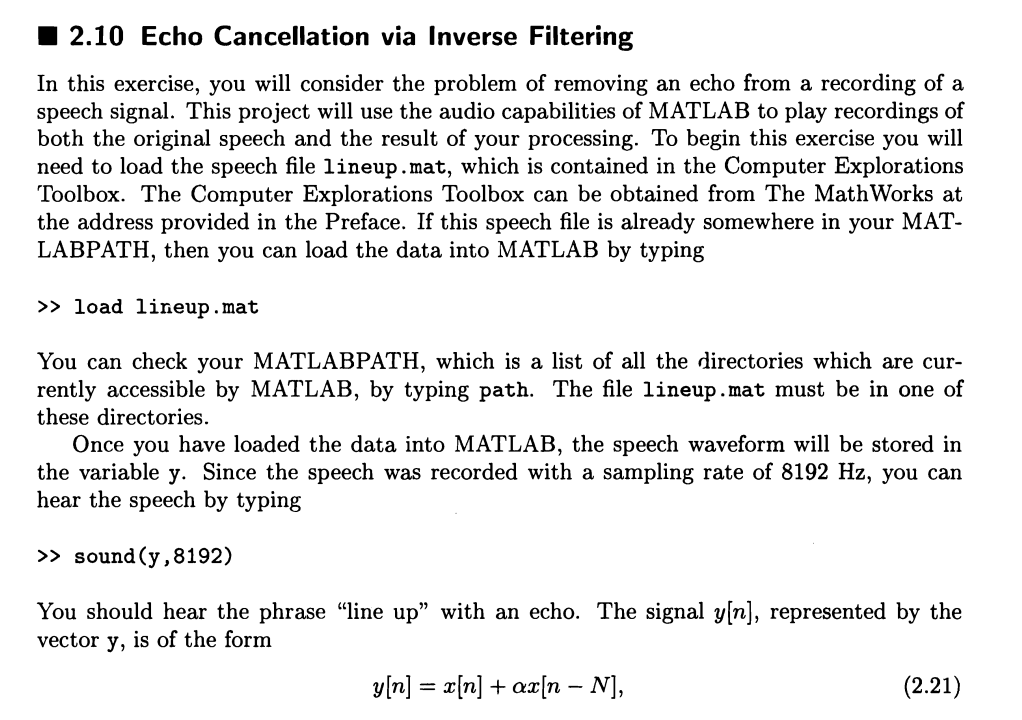

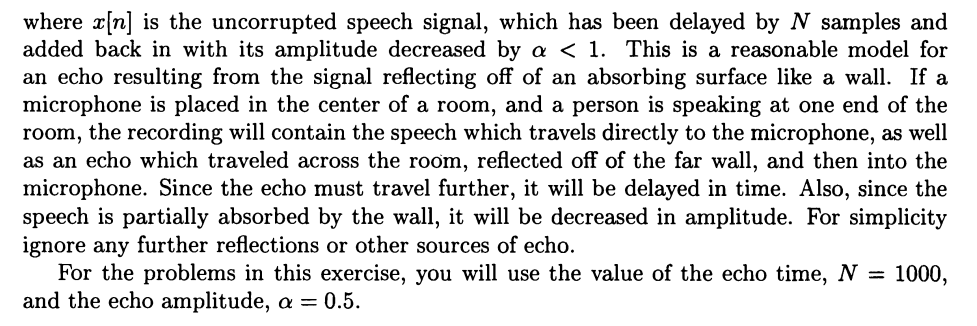

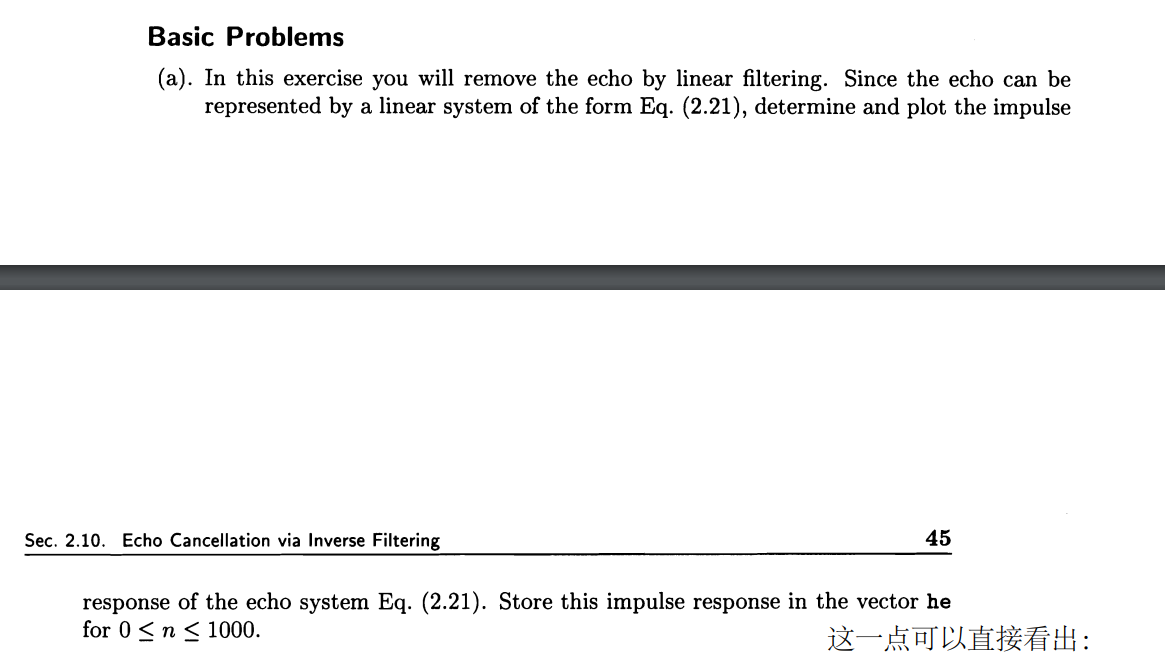

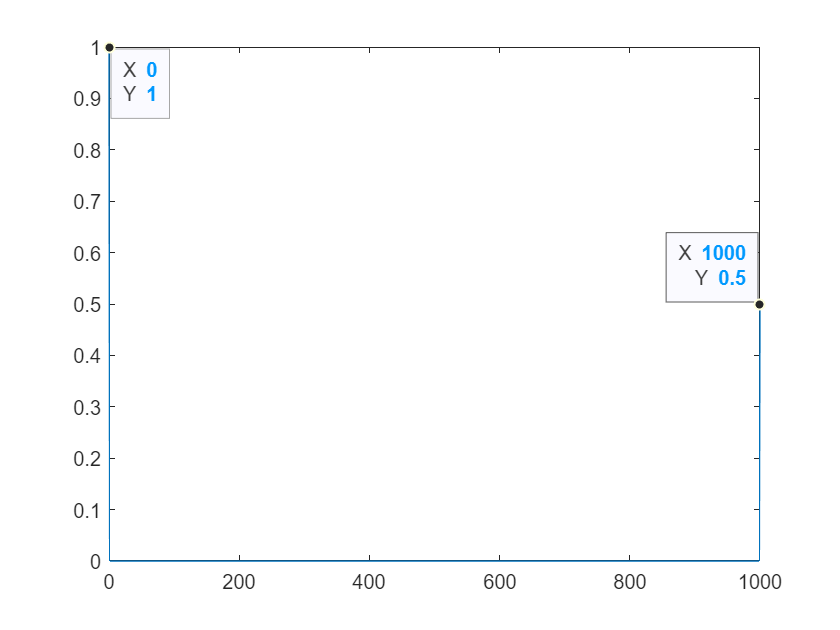

clear; clc;
y = load("lineup.mat");
sound(y.y, 8192)
impu = zeros(1, 1001);
impu(1) = 1;
A = [1];
B = zeros(1, 1001);
B(1) = 1; B(1001) = 0.5;
he = filter(B, A, impu);
f210a = figure;
figure(f210a);
plot(0:1000, he);

ax = gca;
chart = ax.Children(1);
datatip(chart,0,1);
datatip(chart,1000,0.5);

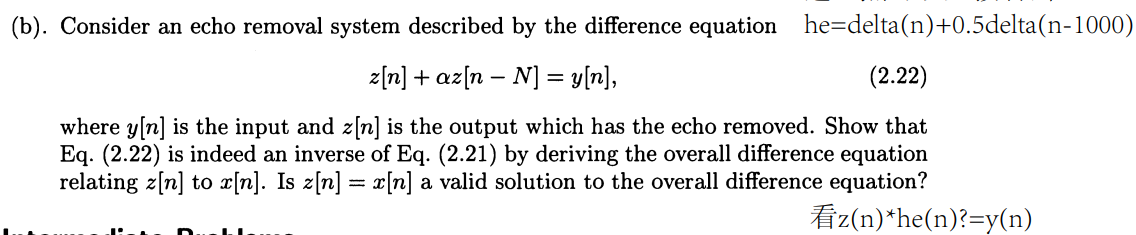

z[n] + 0.5z[n-1000]  = y[n]

y[n] = x[n] + 0.5x[n-1000]

z[n] + 0.5z[n-100]  = x[n] + 0.5x[n-1000]

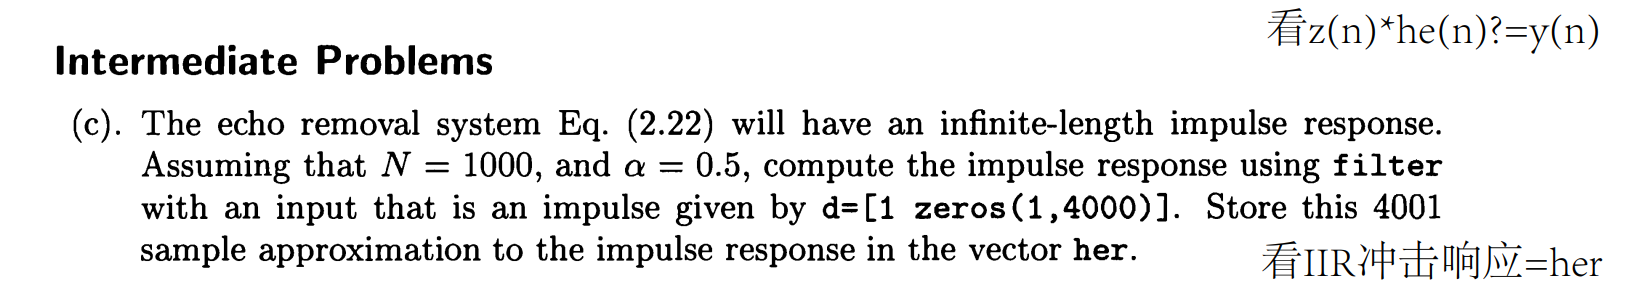

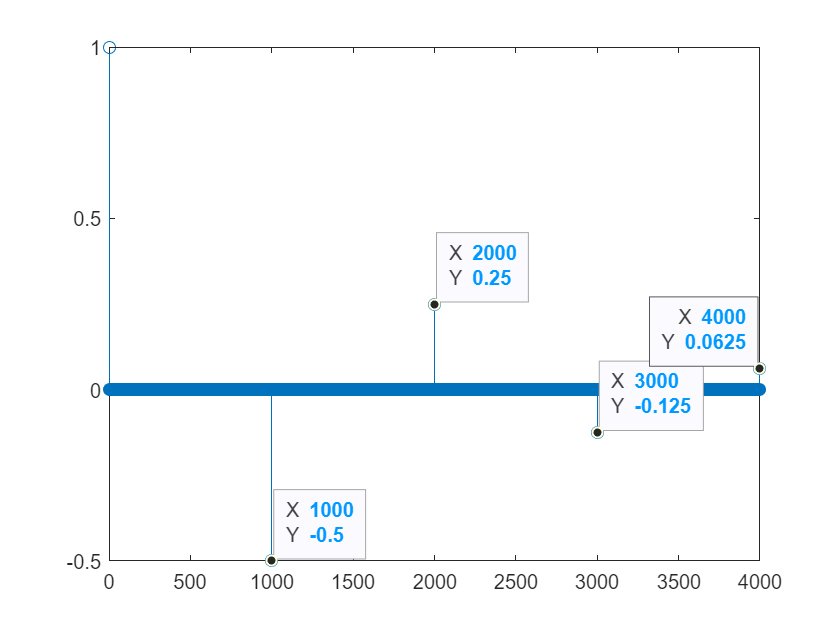

clear; clc;
d = [1 zeros(1, 4000)];
A = [1 zeros(1, 999) 0.5];
B = [1];
her = filter(B, A, d);
f210c = figure;
figure(f210c);
stem(0:4000, her);

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,3000,-0.125);
datatip(chart2,2000,0.25);
datatip(chart2,1000,-0.5);
datatip(chart2,4000,0.0625);

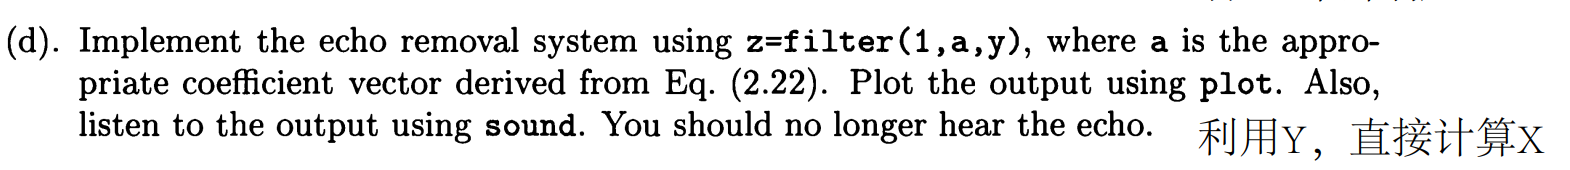

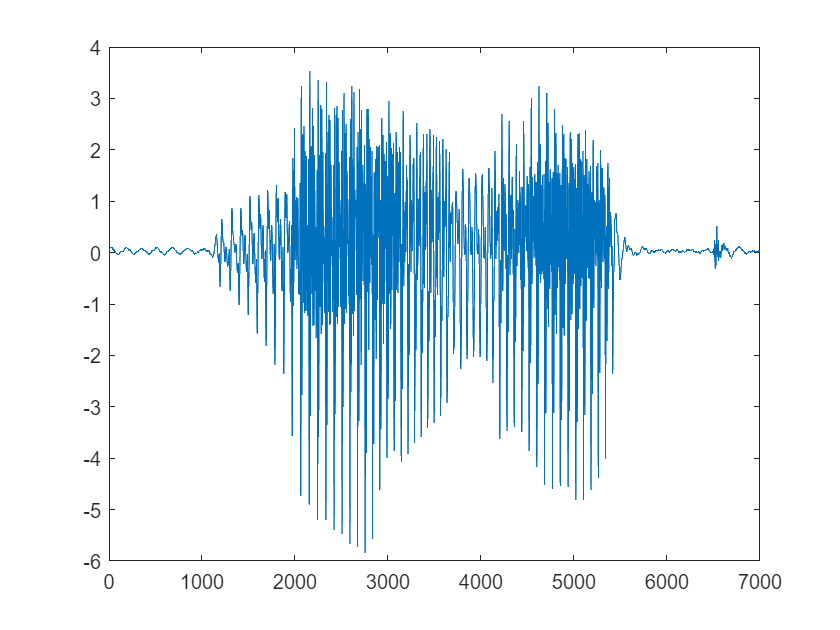

clear; clc;
y = load("lineup.mat");
A = [1 zeros(1, 999) 0.5];
z = filter(1, A, y.y);
sound(z, 8192);
f210d = figure;
figure(f210d);
plot(1:length(z), z);

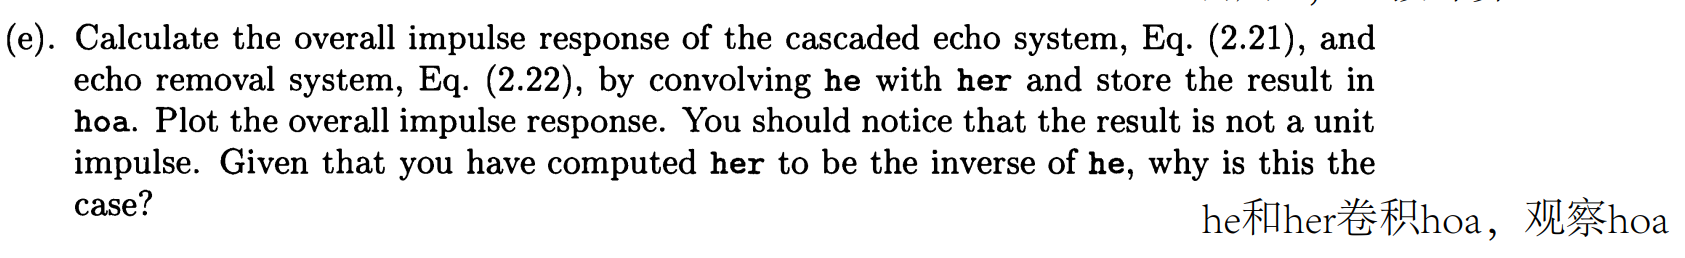

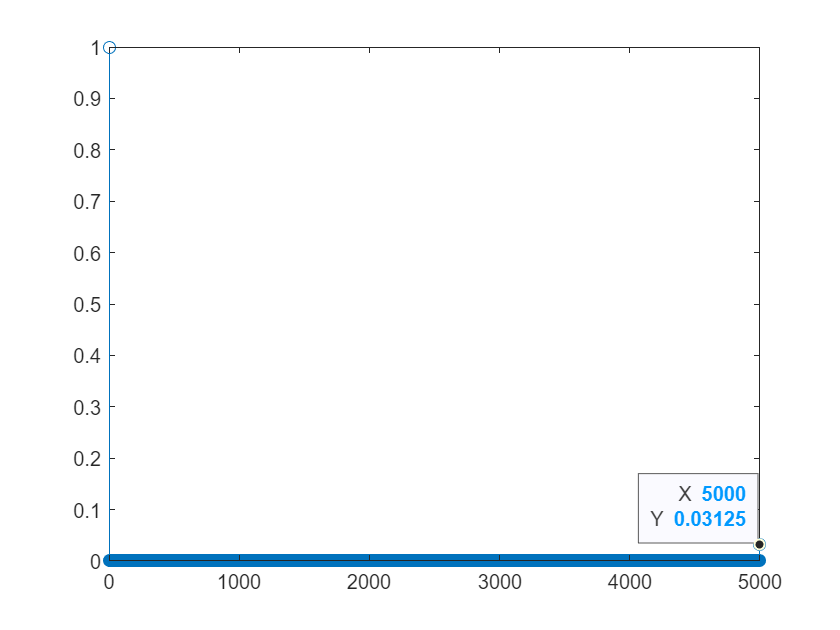

clear; clc;
y = load("lineup.mat");
sound(y.y, 8192)
impu = zeros(1, 1001);
impu(1) = 1;
A = [1];
B = zeros(1, 1001);
B(1) = 1; B(1001) = 0.5;
he = filter(B, A, impu);
nhe = 0:1000;

d = [1 zeros(1, 4000)];
A = [1 zeros(1, 999) 0.5];
B = [1];
her = filter(B, A, d);
nher = 0:4000;

nw = nher(1)+nhe(1):nhe(end)+nher(end);
heConvher = conv(he, her);
f210e = figure;
figure(f210e);
stem(nw, heConvher);